clear;
addChenFunction;

added Chen Functions



dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('D:\p\m\DIC_Analysis\setting_for_real_samples\WE43_T6_C1_setting.mat','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');
[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis']);
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted']);
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

%% [data] strain data. Convert into v7.3 for partial loading
%%
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist



%% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).
clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []                                         %iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));

**How should twinning be affected by different microstructural parameters?**

**(1) The effect of Schmid factor:  (from script_organized_summary_11)**

iE = 5;
eEff = effective_strain(strainFile{iE}.exx, strainFile{iE}.exy, strainFile{iE}.eyy);

% Table_1, for grain summaries
variableNames = {'iE','ID','e1','e5','e10','e50','e90','e95','e99','emean','basal_SF','twin_SF','twinnedTF'};
T = cell2table(cell(0,length(variableNames)));
T.Properties.VariableNames = variableNames;

% Table_2, only for variants of twins
variableNames2 = {'iE','ID','ts','variant','twin_SF','v1_TF','vPct'};
T2 = cell2table(cell(0,length(variableNames2)));
T2.Properties.VariableNames = variableNames2;

ID_twinned = [];
hW = waitbar(0,'do for each grain ...');
NW = length(struCell{iE});
for iS = 1:length(struCell{iE})
    ID_current = struCell{iE}(iS).gID;
    
    ind_local = ismember(ID, ID_current); %ismember(ID, [ID_current,ID_neighbor]);
    % Make it one data point wider on each side
    indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
    indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
    indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
    indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
    
    ID_local = ID(indR_min:indR_max, indC_min:indC_max);
    
    % [*] Calculate the max basal Schmid factor of this grain
    ind = find(ID_current==gID);
    euler_current = [gPhi1(ind),gPhi(ind),gPhi2(ind)];
    [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler_current, [0 0 0], [0 0 0], stressTensor, 'Mg', 'twin');
    basal_SF = max(abs_schmid_factor(1:3,2));
    
    %     uniqueBoundary_local = uniqueBoundary(indR_min:indR_max, indC_min:indC_max);
    map_local = eEff(indR_min:indR_max, indC_min:indC_max);
    map_local(ID_local~=ID_current) = nan;
    
    es = [quantile(map_local(:), [0.01, 0.05, 0.1, 0.5, 0.9, 0.95, 0.99]), nanmean(map_local(:))];
    
    % find out new activeTS
    activeTS = logical(sum(struCell{iE}(iS).cTrueTwin,1));
    if iE==iE_start
        activeTS_pre = [0 0 0 0 0 0];
    else
        activeTS_pre = logical(sum(struCell{iE-1}(iS).cTrueTwin,1));
    end
    newActiveTS = (activeTS - activeTS_pre)>0;      % --> ---------------------------------> we may choose between all activeSS or newActiveSS
    tSFs = struCell{iE}(iS).tSF;
    [~,SF_order]=ismember(tSFs,sort(tSFs,'descend'));   % find index of ranking of element in array
    
    % determine if this grain is twinned. If twinned, twin_SF = max of active twin ss.  If not twinned, twin_SF = max of twin ss.
    if any(activeTS)
        twin_SF = max(struCell{iE}(iS).tSF(sum(struCell{iE}(iS).cTrueTwin,1)>0));
        T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8), basal_SF, twin_SF, true}];
        ID_twinned = [ID_twinned; ID_current];
    else
        twin_SF = max(struCell{iE}(iS).tSF);
        T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8), basal_SF, twin_SF, false}];
    end
    
    % ii is the twin system index from 1 to 6.
    for ii=1:length(activeTS)
        if activeTS(ii)>0
            [~,idx] = max(struCell{iE}(iS).tSF);
            T2 = [T2; {iE, ID_current, struCell{iE}(iS).tLabel(ii), SF_order(ii), tSFs(ii), activeTS(idx)>0, struCell{iE}(iS).tVol(ii)/struCell{iE}(iS).gVol}];
        end
    end
    if rem(iS,10)==1
        waitbar(iS/NW, hW);
    end
end
close(hW);

save('temp_results/tables_for_script_2019_08_iE_5.mat','T','T2');

**(1.1) In grains that are not twinned, we expect higher strain in grains with higher basal Schmid factor.  This is because WE43-T5 has a weak texture, which favors basal slip.**

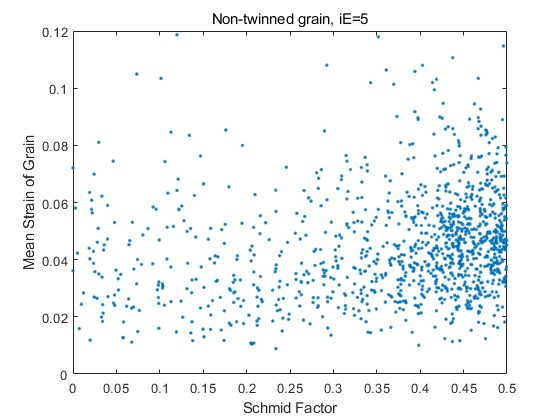

%% [*] [Plot] selected strain (e.g., median strain vs. basal_SF)
ind = (T.twinnedTF==0);                 % ---------------------------> Select which (twinned or non-twinned) grain
vx = T.basal_SF(ind);                    % ---------------------------> Select which SF here
vy = T.emean(ind);                      % ---------------------------> Select strain here
ylabel_str = 'Mean Strain of Grain';    % ---------------------------> change name
title_str = ['Non-twinned grain, iE=',num2str(iE)];

figure;disableDefaultInteractivity(gca);
plot(vx, vy, '.');
set(gca,'ylim',[0 0.12])
xlabel('Schmid Factor'); ylabel(ylabel_str);
title(title_str,'fontweight','normal');

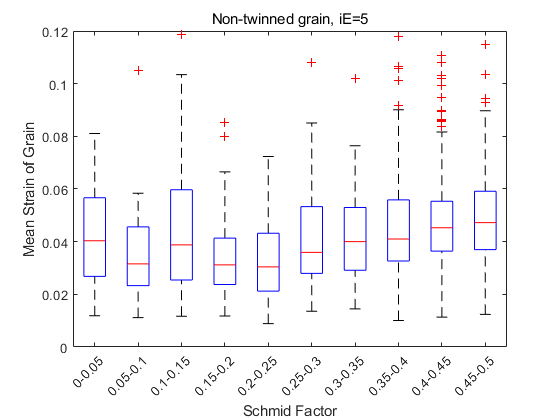


% [*] Summarize by [boxplot].
edges = 0:0.05:0.5;
gv = discretize(vx, edges);
nGroups = length(edges)-1;
clear labels;
for ii = 1:length(edges)-1
    labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
end

figure;disableDefaultInteractivity(gca);
boxplot([vy; nan*ones(nGroups,1)], [gv; (1:nGroups)']);     % sometimes, a group does not have anything. This make sure we have all group variables.
xlabel('Schmid Factor'); ylabel(ylabel_str);
set(gca,'xticklabels',labels,'xticklabelrotation',45);
set(gca,'ylim',[0 0.12]);
title(title_str,'fontweight','normal');

**(1.2) For grains that are twinned:**

**(1.2 a) The twin variant area as a fraction of grain size tend to increase with increasing twin variant Schmid factor. **

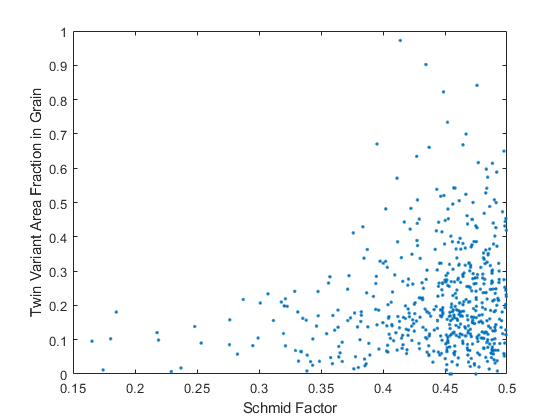

%% [*] [boxplot] to show twin_area_fraction vs twin_SF
edges = 0:0.05:0.5;
vx = T2.twin_SF;                   % ---------------------------> Select which SF here
vy = T2.vPct;                      % ---------------------------> Select strain here
ylabel_str = 'Twin Variant Area Fraction in Grain';    % ---------------------------> change name

figure;disableDefaultInteractivity(gca);
plot(vx, vy, '.');
xlabel('Schmid Factor'); ylabel(ylabel_str);

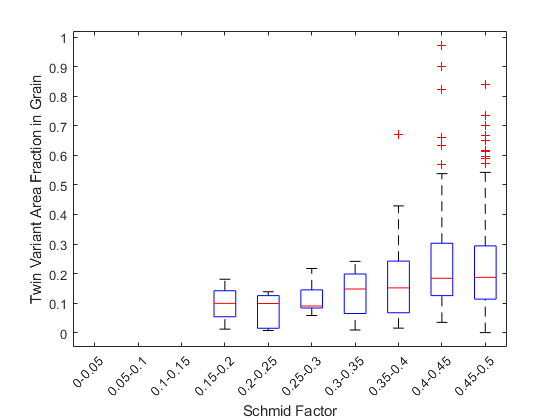

% set(gca,'ylim',[0 0.1])

gv = discretize(vx, edges);
nGroups = length(edges)-1;
clear labels;
for ii = 1:length(edges)-1
    labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
end
figure;disableDefaultInteractivity(gca);
boxplot([vy; nan*ones(nGroups, 1)], [gv; (1:nGroups)']);
xlabel('Schmid Factor'); ylabel(ylabel_str)
set(gca,'xticklabels',labels,'xticklabelrotation',45);

**(1.2 b) We look at the distribution of twin variant Schmid factor.  (Based on script_organized_summary_1)**

variableNames = {'ID','iE','iTwin','twinnedTF','tSF'};
T3 = cell2table(cell(0,length(variableNames)));
T3.Properties.VariableNames = variableNames;

variableNames = {'ID','iE','gDia','twinnedTF','tSF','tAF'};
T4 = cell2table(cell(0,length(variableNames)));
T4.Properties.VariableNames = variableNames;

um_per_dp = 5*360/4096;    % micron per data point, ~0.43

h = waitbar(0,'processing data...');
NW = length(struCell{iE});
for iS = 1:length(struCell{iE})
    ID_current = struCell{iE}(iS).gID;
    % Find if variant is twinned
    twinnedTF = [];
    for ie = iE_start:iE
        twinnedTF(ie-iE_start+1,:) = sum(struCell{ie}(iS).cTrueTwin,1);
    end
    twinnedTF = logical(sum(twinnedTF,1));
    for iTwin = 1:6
        T3 = [T3;{ID_current, iE, iTwin, twinnedTF(iTwin), struCell{iE}(iS).tSF(iTwin)}];
    end
    
    gd = sqrt(4*struCell{iE}(iS).gVol/pi) * um_per_dp;
    vol_t = sum(struCell{iE}(iS).tVol);
    vol_g = struCell{iE}(iS).gVol;
    if any(twinnedTF)
        T4 = [T4;{ID_current, iE, gd, true, max(struCell{iE}(iS).tSF(:).*twinnedTF(:)), vol_t/vol_g}];
    else
        T4 = [T4;{ID_current, iE, gd, false, max(struCell{iE}(iS).tSF(:).*(~twinnedTF(:))), vol_t/vol_g}];
    end
    if rem(iS,10)==1
        waitbar(iS/NW, h);
    end
end
close(h);


**We observed that, the counts of active twin variants increases with the increase of twin variant Schmid factor.**

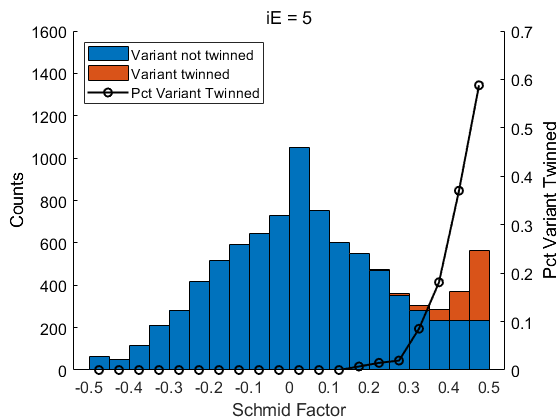

edges = -0.5:0.05:0.5;
ind = T3.twinnedTF == 1;
[N_t,~] = histcounts(T3.tSF(ind), edges);
[N_nt,~] = histcounts(T3.tSF(~ind), edges);

figure; hold on; disableDefaultInteractivity(gca);
bar(edges(1:end-1)+0.025, [N_nt(:), N_t(:)], 1, 'stacked');
set(gca,'fontsize',12, 'XTick',-0.5:0.1:0.5,'ylim',[0 1600]);
xlabel('Schmid Factor');
ylabel('Counts');

yyaxis right;
set(gca, 'ycolor', 'k');
ylabel('Pct Variant Twinned');
plot(-0.475:0.05:0.475, N_t./(N_t+N_nt),'-ko','linewidth',1.5);

title(['iE = ',num2str(iE)],'fontweight','normal');
legend({'Variant not twinned', 'Variant twinned','Pct Variant Twinned'},'Location','northwest');

**(2) The effect of grain size is not significant.  The counts of twinned grains slightly increase with increasing grain diameter.  But this might be an artifact, because small grains are difficult to label? **

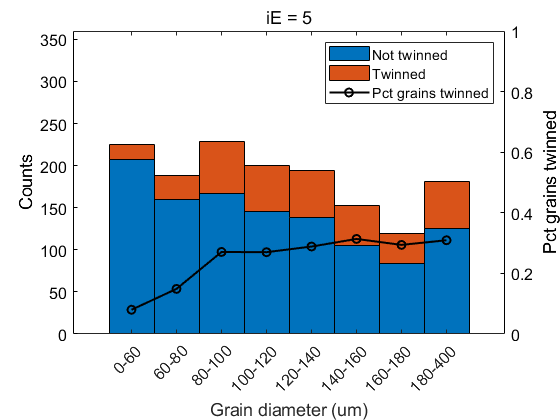

all_dia = sort(T4.gDia);
inds = floor(linspace(1,length(all_dia),9));
edges_gd = all_dia(inds);

edges_gd =[0,60:20:180,400];

ind = T4.twinnedTF==1;
[N_t,~] = histcounts(T4.gDia(ind), edges_gd);
[N_nt,~] = histcounts(T4.gDia(~ind), edges_gd);

d_int = (edges_gd(3)-edges_gd(2))/2;
xpos = [edges_gd(2)-d_int, edges_gd(2:end-1)+d_int];
xstr = [];
for ii=1:length(edges_gd)-1
    xstr{ii} = [num2str(edges_gd(ii)),'-',num2str(edges_gd(ii+1))];
end

figure;disableDefaultInteractivity(gca);
bar(xpos, [N_nt(:),N_t(:)], 1, 'stacked');
xlabel('Grain diameter (um)');
ylabel('Counts');
set(gca,'ylim',[0 360]);

yyaxis right;
set(gca,'ycolor','k','xTickLabels',xstr,'xTickLabelRotation',45);
plot(xpos, N_t./(N_t+N_nt),'-ko','linewidth',1.5);
ylabel('Pct grains twinned');
legend('Not twinned','Twinned','Pct grains twinned','location','northeast');
set(gca,'fontsize',12,'ylim',[0 1]);
title(['iE = ',num2str(iE)],'fontweight','normal');

**Now we use a histogram of counts of grain diameter as a background, to show how twinned area fraction changes w.r.t grain diameter.**

**The twinned area fraction in each grain seems to be decreasing with increasing grain diameter.  This might also be an artifcat, as smaller grains might have twinned areas labeled larger than it should be, due to relatively large area of noise.  **

**Note that, the notches are 95% confidence intervals of the median.  So it shows that the median is not significantly different (because notches overlap).**

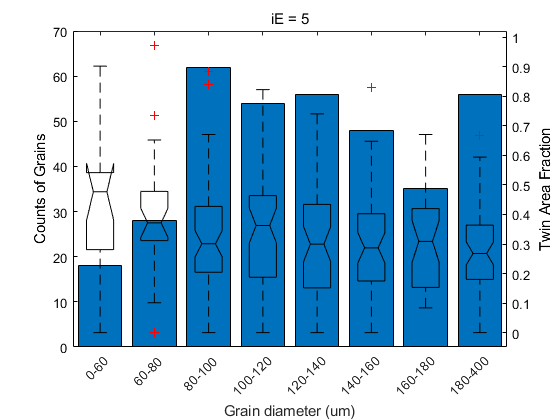

ind = T4.twinnedTF==1;
[N_t,~] = histcounts(T4.gDia(ind), edges_gd);

gDia_t = T4.gDia(ind);  % (1) Use this as the grouping criterion
tAF_t = T4.tAF(ind);    % (2) This is the data to summarize the distribution, by box, in each group
gv = discretize(gDia_t, edges_gd);  % grouping variable: grain diameter 
nGroups = length(edges_gd) - 1; 

figure; hold on; disableDefaultInteractivity(gca);
bar(xpos, N_t(:));
xlabel('Grain diameter (um)');
ylabel('Counts of Grains');

yyaxis right;
boxplot([tAF_t;nan*ones(nGroups,1)], [gv; (1:nGroups)'], 'position', xpos,'color','k','notch','on');  % make sure every group number has a 'NaN' element 
ylabel('Twin Area Fraction');
set(gca,'ycolor','k','xTickLabels',xstr,'xTickLabelRotation',45);
title(['iE = ',num2str(iE)],'fontweight','normal');

**So, if we consider the effect of grain size in the above two plots as an artifact, then a possible explanation might be: twins are difficult to label in small grains.  But when it does get labeled, it is likely to account for a large percentage of grain size for a small grain.**

**It's better to plot grains with diameter <80um to better visualize how they actually look.  (1) TrueTwinMap (2) Strain map**

matrix is big, use reduced ratio = 5


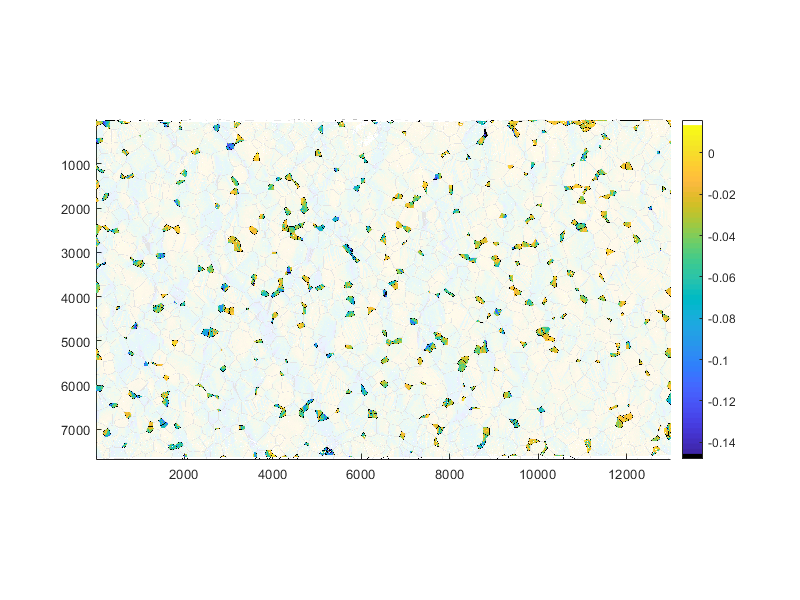

gDia_th = 80;
mask = 0.1*ones(size(ID));
list_IDs = gID(dataFile.gDiameter < gDia_th);
mask(ismember(ID,list_IDs)) = 1;

myplotm(strainFile{iE}.exx,'TF',boundaryTFB,'alpha',mask);

matrix is big, use reduced ratio = 5


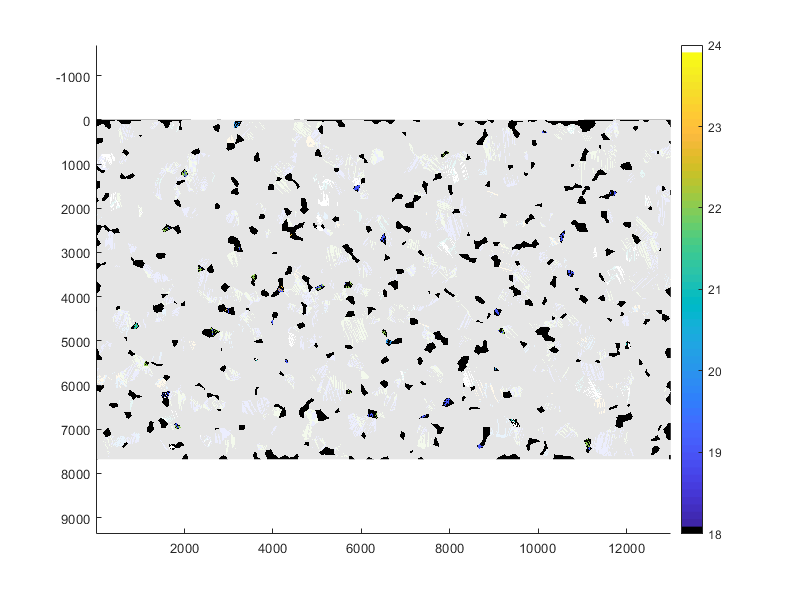

ans =     18    24


myplotm(trueTwinMapCell{iE},'TF',boundaryTFB,'alpha',mask); ca([18,24])

**(3) Now, something interesting.  We categorize the grain boundary into different groups, and look at how twinning activity is affected by the neighboring grains at these grain boundaries.  **

% For each grain, summarize a [b#,g#] pair for distMap purpose, for each twin activity.     
% Also, generate one data point from the mantle, contribution to one of the previous defined regions.  
eMap = calculate_effective_strain(strainFile{iE-1}.exx, strainFile{iE-1}.exy, strainFile{iE-1}.eyy);
NN = 250;
x_dist = (1:NN)';
qs_target = [0.0014, 0.0227, 0.1587, 0.5, 0.8414, 0.9772, 0.9987];
mm = 0;
MM = 150;
% The analysis takes time, but we may directly load some results.  
try
    load(['temp_results/quantile_summary/quantile_summary_wrt_gb_',num2str(iE),'.mat']);
catch
    error("cannot load");
end

%% can plot distance map to illustrate
if 0
    myplot(distMap_not_involved,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_slip_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_slip_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_co_found,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_twin_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_twin_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_slip_growth_a,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_slip_growth_b,boundaryTFB + logical(trueTwinMapCell{iE}));
    myplot(distMap_co_growth,boundaryTFB + logical(trueTwinMapCell{iE}));    
end

**The effect of high strain on twin growth/activation:**

**Here we plot the median/mean/etc of effective strain for all data points at distances=1,2,3,... to gb, for different categories**

**--> If we have slip on one side of gb, and twinning on the otherside.  At the previous strain level, slip side strain was highest.**

**--> slip-slip, and slip side of slip-new twin pair, also tend to have high strain.**

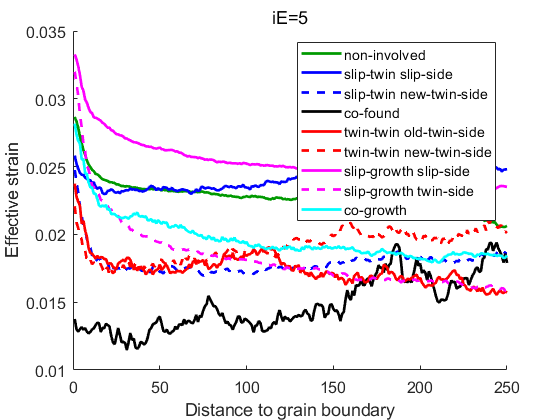


ith = 4;
figure; hold on;
nPts = length(x_dist);    % or 150
% ndp_to_plot = 150;
plot(x_dist(1:nPts),q_not_involved(ith,1:nPts),'-','color',[0 0.6 0],'LineWidth',2);
plot(x_dist(1:nPts),q_slip_twin_a(ith,1:nPts),'-b','LineWidth',2);
plot(x_dist(1:nPts),q_slip_twin_b(ith,1:nPts),'--b','LineWidth',2);

plot(x_dist(1:nPts),q_co_found(ith,1:nPts),'-k','LineWidth',2);
plot(x_dist(1:nPts),q_twin_twin_a(ith,1:nPts),'-r','LineWidth',2);
plot(x_dist(1:nPts),q_twin_twin_b(ith,1:nPts),'--r','LineWidth',2);

plot(x_dist(1:nPts),q_slip_growth_a(ith,1:nPts),'-m','LineWidth',2);
plot(x_dist(1:nPts),q_slip_growth_b(ith,1:nPts),'--m','LineWidth',2);
plot(x_dist(1:nPts),q_co_growth(ith,1:nPts),'-c','LineWidth',2);

legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
set(gca,'fontsize',12);
xlabel('Distance to grain boundary');
ylabel('Effective strain');
title(['iE=',num2str(iE)],'fontweight','normal');

% set(gca,'ylim',[0.015 0.04]);
%% --> maybe check, find out the points that represent the median.  See where it is located.

**For each category, take all data points in all grains within a mantle of size <150 to gb, use a boxplot to show the strain distribution.**

**The trend is similar, e.g., the slip side of slip-twin growth region tend to have the highest strain.**

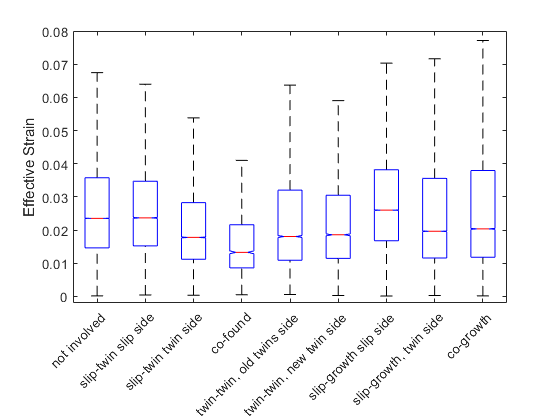

%% boxplot to summarize the strain distribution in a mantle of [0,150] data point size, for different types of regions.
% (1) not involved, (2) slip-induced-twin, slip side, (3) slip-induced-twin, twin side,
% (4) co-found, (5) twin-induced-twin, old twin side, (6) twin-induced-twin, new twin side,
% (7) slip-induced-growth, slip side, (8) slip-induced-growth, twin side, (9) co-growth 
close all;
mm = 0;
MM = 150;
v = [];
g = [];
ind = (distMap_not_involved>mm)&(distMap_not_involved<MM);
v = [v; eMap(ind)];
g = [g; 1*ones(sum(ind(:)),1)];
ind = (distMap_slip_twin_a>mm)&(distMap_slip_twin_a<MM);
v = [v; eMap(ind)];
g = [g; 2*ones(sum(ind(:)),1)];
ind = (distMap_slip_twin_b>mm)&(distMap_slip_twin_b<MM);
v = [v; eMap(ind)];
g = [g; 3*ones(sum(ind(:)),1)];

ind = (distMap_co_found>mm)&(distMap_co_found<MM);
v = [v; eMap(ind)];
g = [g; 4*ones(sum(ind(:)),1)];
ind = (distMap_twin_twin_a>mm)&(distMap_twin_twin_a<MM);
v = [v; eMap(ind)];
g = [g; 5*ones(sum(ind(:)),1)];
ind = (distMap_twin_twin_b>mm)&(distMap_twin_twin_b<MM);
v = [v; eMap(ind)];
g = [g; 6*ones(sum(ind(:)),1)];

ind = (distMap_slip_growth_a>mm)&(distMap_slip_growth_a<MM);
v = [v; eMap(ind)];
g = [g; 7*ones(sum(ind(:)),1)];
ind = (distMap_slip_growth_b>mm)&(distMap_slip_growth_b<MM);
v = [v; eMap(ind)];
g = [g; 8*ones(sum(ind(:)),1)];
ind = (distMap_co_growth>mm)&(distMap_co_growth<MM);
v = [v; eMap(ind)];
g = [g; 9*ones(sum(ind(:)),1)];

figure;
% reduce number of points to plot faster
boxplot(v(1:100:end),g(1:100:end),'Notch','on','symbol','');
set(gca,'ylim',[-0.002, 0.08]);
set(gca,'xticklabel',{'not involved','slip-twin slip side','slip-twin twin side',...
    'co-found','twin-twin, old twins side','twin-twin, new twin side',...
    'slip-growth slip side','slip-growth, twin side','co-growth'},'xticklabelrotation',45);
ylabel('Effective Strain');

**In a similar way, in the code above, for each grain, calculate the quantiles of all data points' strain within a distance [0,150] to the boundary of the specific category.  Then for each category, summarize by boxplot to show the distribution of these quantiles/etc.**

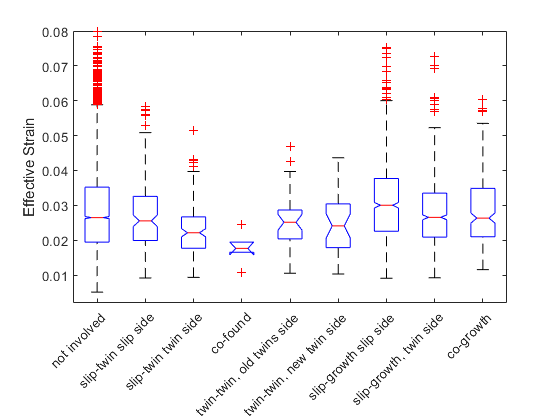

%% For each grain, generate one data point from the mantle, contribution to one of the previous defined regions.  Could combine, but maybe better to run each section for each method.
% (1) not involved, (2) slip-induced-twin, slip side, (3) slip-induced-twin, twin side,  
% (4) co-found, (5) twin-induced-twin, old twin side, (6) twin-induced-twin, new twin side,
% (7) slip-induced-growth, slip side, (8) slip-induced-growth, twin side, (9) co-growth 
ith = 8;
vv = [];
gg = [];
try
vv = [vv;qs_not_involved(:,ith)];
gg = [gg; 1 * ones(size(qs_not_involved,1),1)];
catch
end
try
vv = [vv;qs_slip_twin_a(:,ith)];
gg = [gg; 2 * ones(size(qs_slip_twin_a,1),1)];
catch
end
try
vv = [vv;qs_slip_twin_b(:,ith)];
gg = [gg; 3 * ones(size(qs_slip_twin_b,1),1)];
catch
end
try
vv = [vv;qs_co_found(:,ith)];
gg = [gg; 4 * ones(size(qs_co_found,1),1)];
catch
end
try
vv = [vv;qs_twin_twin_a(:,ith)];
gg = [gg; 5 * ones(size(qs_twin_twin_a,1),1)];
catch
end
try
vv = [vv;qs_twin_twin_b(:,ith)];
gg = [gg; 6 * ones(size(qs_twin_twin_b,1),1)];
catch
end
try
vv = [vv;qs_slip_growth_a(:,ith)];
gg = [gg; 7 * ones(size(qs_slip_growth_a,1),1)];
catch
end
try
vv = [vv;qs_slip_growth_b(:,ith)];
gg = [gg; 8 * ones(size(qs_slip_growth_b,1),1)];
catch
end
try
vv = [vv;qs_co_growth(:,ith)];
gg = [gg; 9 * ones(size(qs_co_growth,1),1)];
catch
end

figure;
boxplot(vv,gg,'Notch','on');
set(gca,'ylim',[0.002, 0.08]);
set(gca,'xticklabel',{'not involved','slip-twin slip side','slip-twin twin side',...
    'co-found','twin-twin, old twins side','twin-twin, new twin side',...
    'slip-growth slip side','slip-growth, twin side','co-growth'},'xticklabelrotation',45);
ylabel('Effective Strain');

**An interesitng question to ask is, what is a reasonable distance to summarize these things.**

**We could plot the distMap, and see how 150 data points mantle look like.**

matrix is big, use reduced ratio = 5


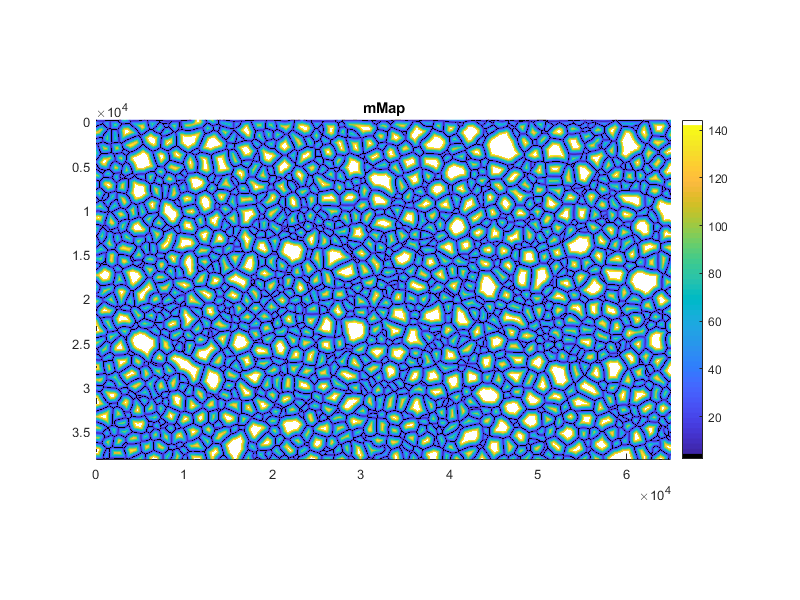

mMap = dataFile.distMap;
mMap(mMap>150) = nan;
myplotm(mMap,'X',X,'Y',Y,'TF',boundaryTFB);